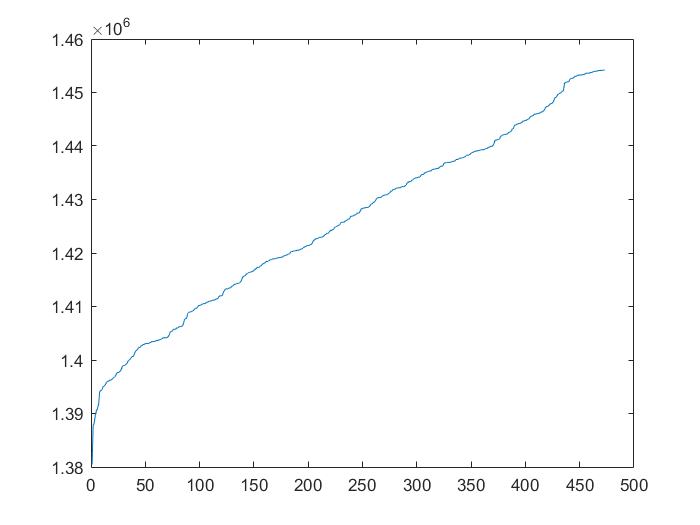

clear;clc;close all;
files = dir('\\longde\longde\008-投标中心\006-数据分析中心\投标数据Excel文件汇总\*.xlsx');
indx = randi(length(files), 1);
filename = ['\\longde\longde\008-投标中心\006-数据分析中心\投标数据Excel文件汇总\', files(indx).name];
try
    file = readtable(filename, 'Sheet', 1, 'VariableNamingRule', 'preserve');
    Gn = file.("投标报价");
catch ME
    file = readtable(filename, 'Sheet',  '开标信息', 'VariableNamingRule', 'preserve');
    Gn = file.("投标报价");
end
R = file.("扣分系数");
% 去掉空白值
index = isnan(Gn);
Gn(index) = [];
R(index) = [];
% 排序
bidCount = length(Gn);
[Gn_sort, index] = sort(Gn);
R_sort = R(index);
if bidCount > 19
    % 采用去尾法取整
    cut = floor(0.2 * bidCount);
elseif bidCount > 4
    % 首尾去掉 1 个
    cut = 1;
else
    cut = 0;
end
% 去最高最低平均价 P
Gn_cal = Gn_sort(cut+1 : bidCount-cut);
R_cal = R_sort(cut+1 : bidCount-cut);
P = mean(Gn_cal);
figure
plot(Gn_sort);

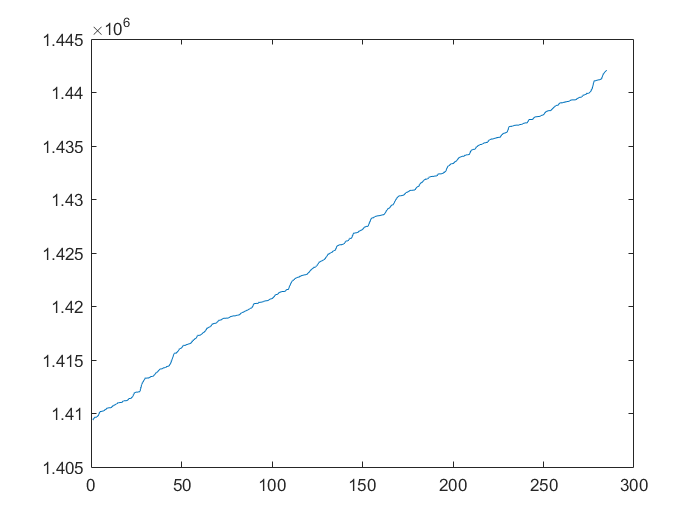

figure
plot(Gn_cal);